## EigenShoe runner

Links all the functions together

### Load images

% LoadImagesAndScale;
% names = ["BlackDiamond", "kronos", "LaSportiva"];
% Original test set, not needed anymore

names = ["Ansazi", "Instincts", "RedLine", "Spire"];
[IMAGE_DIM, IMAGE_SIZE, num_shoes, Shoes, Lookup] = LoadImages( names , 4);

Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Ansazi1.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Ansazi2.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Ansazi3.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Ansazi4.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Instincts1.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Instincts2.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Instincts3.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Instincts4.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\RedLine1.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\RedLine2.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\RedLine3.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\RedLine4.jpg
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Train\Spire1.j



% Get only the right facing shoes ie numbers 1,2 but not 3,4 and 5,6 but not 7,8
newShoes = zeros(IMAGE_SIZE, num_shoes / 2);

for i = 1:num_shoes
    good = mod(floor((i - 1) / 2), 2) == 0;

    if good
        newShoes(:, floor((i - 1) / 2) + 1) = Shoes(:, i);
    end

end
Shoes = newShoes

Shoes =    199     0   195     0   190     0   191     0     0
   204     0   190     0   189     0   193     0     0
   202     0   191     0   191     0   190     0     0
   198     0   195     0   192     0   193     0     0
   200     0   192     0   191     0   192     0     0
   204     0   188     0   192     0   193     0     0
   204     0   193     0   188     0   191     0     0
   203     0   195     0   190     0   191     0     0
   204     0   191     0   189     0   193     0     0
   203     0   194     0   191     0   192     0     0


## Get SVD

Do it around mean subtracted, so we have negative and positive sigma values, centering all of our data.

avgShoe = mean(Shoes,2);

Shoes = Shoes-avgShoe*ones(1,size(Shoes,2));
[U,S,V] = svd(Shoes,'econ');



norm(Shoes - U * S * V');
disp("How close the svd is to the matrix: " + num2str(ans));

How close the svd is to the matrix: 2.5285e-11


### Plot our SVD and average face

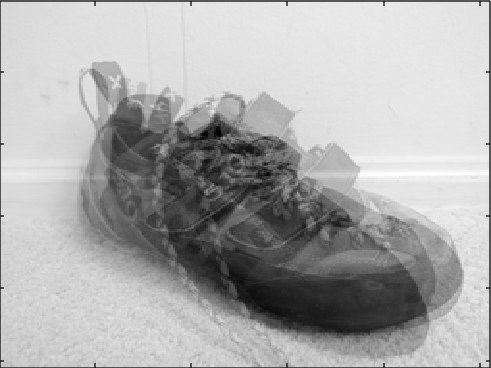

figure(1), axes('position',[0  0  1  1]), axis off
imagesc(reshape(avgShoe, IMAGE_DIM, IMAGE_DIM))
title("avg shoe"), colormap gray;

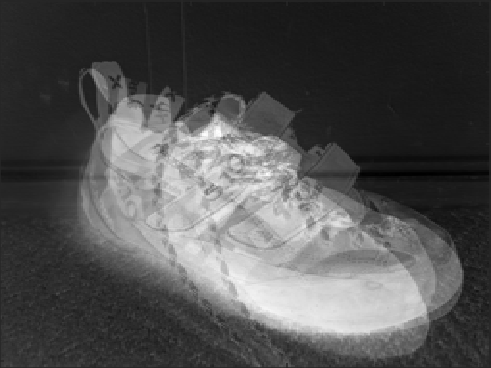


figure(2), axes('position',[0  0  1  1]), axis off
title("first eigenshoe"), colormap gray;
imagesc(reshape(U(:,1), IMAGE_DIM, IMAGE_DIM))

## Get r values

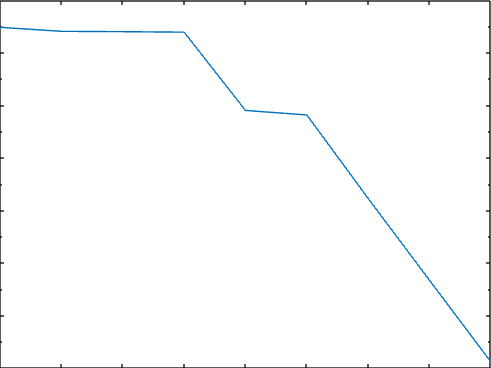

semilogy(diag(S)), grid off
xlabel('r')
ylabel('Singular value, \sigma_r')

## Plot all calculated eigenfaces

n = IMAGE_DIM;
m = IMAGE_DIM;
EigenShoes = zeros(n*3, m*2);
count = 1;
disp("EIGEN")

EIGEN


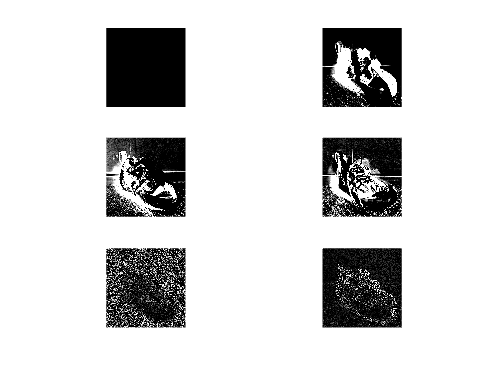

figure(2)
for i = 1:3
    for j = 1:2
        EigenShoes(1+(i-1)*n : i*n , 1+(j-1)*m : j*m) ...
            = reshape(U(:,count), n, m);
        subplot(3,2, count);
        imshow((reshape(U(:,count), n, m) + 0) * 500);

        count = count + 1;
    end
end

disp("EGFACE")

EGFACE


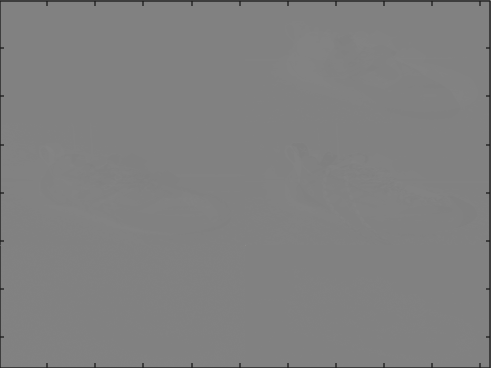

figure(1), axes('position',[0  0  1  1]), axis off
imagesc(EigenShoes), colormap gray;


% Some are positive and negative, I could try to put it in a sigmoid
% functoin and mult by 255 ??


## Now show eigenface reconstruction of image that was omitted from test set

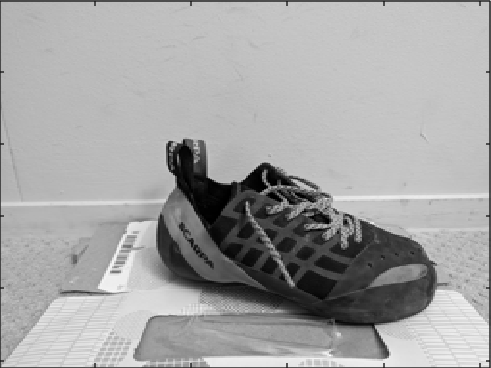

testFace = imread("Test/Test.jpg");
testFace = im2gray(testFace);
testFace = imresize(testFace, [IMAGE_DIM, IMAGE_DIM]);
imagesc(reshape(testFace,n,m))

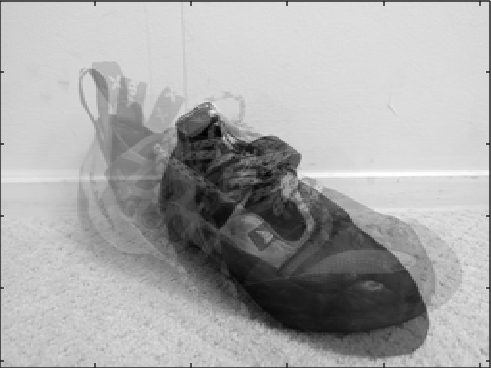

testFace = reshape(double( im2gray(testFace) ) , IMAGE_SIZE, 1);

testFaceMS = testFace - avgShoe;
count = 1;
for r=[6] 
    reconShoe = avgShoe + (U(:,1:r)*(U(:,1:r)'*testFaceMS));
    imagesc(reshape(reconShoe,n,m))
    figure(count), axes('position',[0  0  1  1]), axis off
    title(['r=',num2str(r, "%d")])
    count = count + 1;
end

## Project person 2 and 7 onto PC5 and PC6

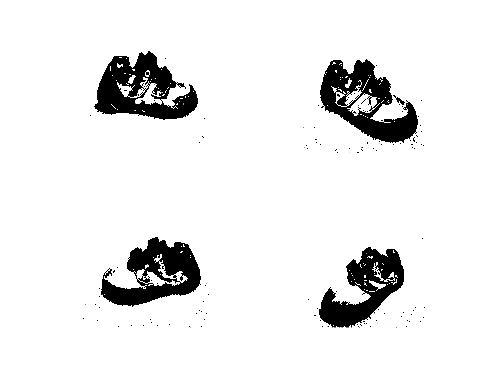

close
Shoe1 = Shoes(:, [1, 2]);
Shoe2 = Shoes(:, [3, 4]);

both = [ Shoe1 Shoe2];

figure

for i = 1 : size(both, 2)
    img = reshape( both(:, i) , IMAGE_DIM, IMAGE_DIM);
    subplot(2, 2, i)
    imshow(img);
end

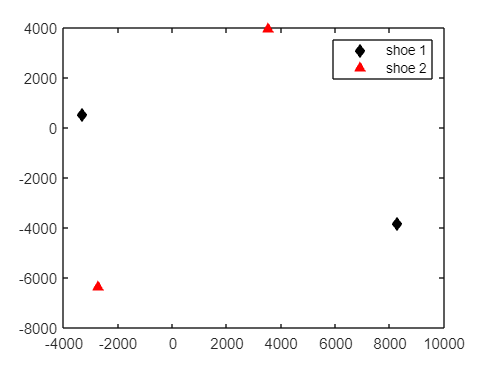



Shoe1 = Shoe1 - avgShoe*ones(1,size(Shoe1,2));
Shoe2 = Shoe2 - avgShoe*ones(1,size(Shoe2,2));

PCAmodes = [3, 4, 5];    % Project onto PCA modes 5 and 6
PCACoordsP1 = U(:,PCAmodes)'*Shoe1;
PCACoordsP2 = U(:,PCAmodes)'*Shoe2;

figure

axis off
plot(PCACoordsP1(1,:),PCACoordsP1(2,:),'kd', 'MarkerFaceColor', 'k')
hold on
plot(PCACoordsP2(1,:),PCACoordsP2(2,:),'r^', 'MarkerFaceColor', 'r')
legend('shoe 1', 'shoe 2')